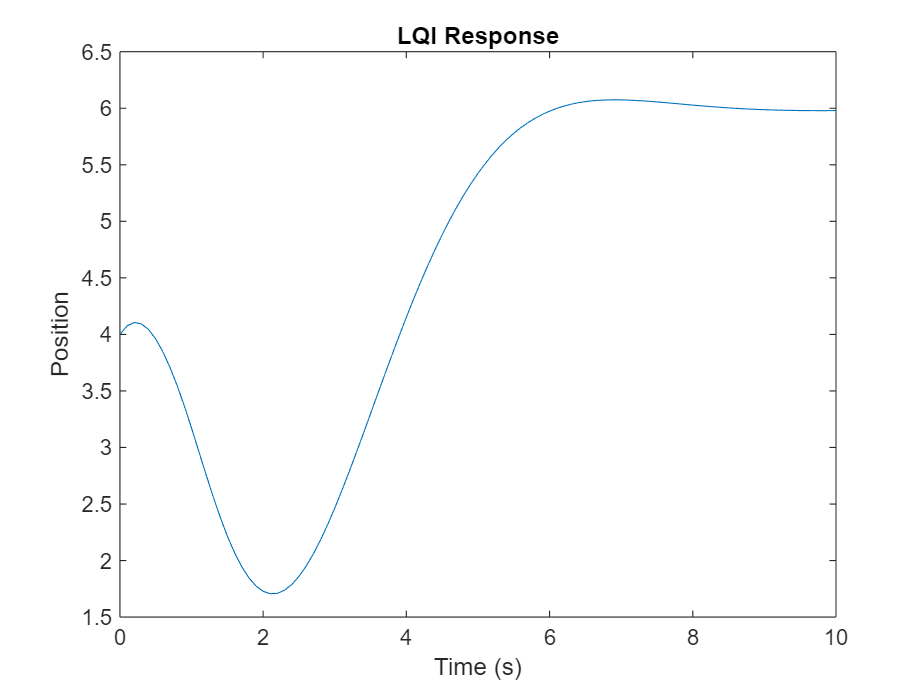

test =     3.9835    4.9815    5.9798    3.9835    3.9835    3.9835    4.9815    4.9811    4.9811    7.9756    4.9811    5.9791
    0.0012    0.0042    0.0067   -0.0031   -0.0031   -0.0031    0.0042    0.0007    0.0007    0.0088    0.0007    0.0038


test2 =     3.9996
    4.9989
    5.9982
    4.0002
    4.0002
    4.0002
    4.9989
    4.9995
    4.9995
    7.9973


test3 =     9.2867
   11.6138
   13.9406
    9.2824
    9.2824
    9.2824
   11.6138
   11.6098
   11.6098
   18.5905





clear, close all



%Lets test out LQR
m = 1;
k = 1;
b = 1;


Q = [100 0
     0  1];



R = 1;



Q_lqi = [.1 0 0
         0 1 0
         0 0 1];
%plot(t_LQR,x_LQR(:,1))
%plot(t_LQR,input)

%Let make a function which takes in a q(3nx1), vel(3nx1),ref_q(3nx1),
%tspan, on off for fullsim

q0 = [4 4 4 4 4 4 4 4 4 4 4 4]';
q_ref = [4 5 6 4 4 4 5 5 5 8 5 6]';
vel_act = [0 0 0 1 1 1 0 1 1 1 1 1]';


tstep = .1;
umax = 60;
integral_in = [0 0 0 0 0 0 0 0 0 0 0 0]';
[test,test2,test3] = LQI_control(Q_lqi,R,m,b,k,umax,q0,vel_act,q_ref,tstep,true,integral_in)



%Lets tryout LQI control :)
function [next_state, u_out, updated_integral] = LQI_control(Q, R, m, b, k, u_max, q_act, vel_act, q_ref, tstep, fullsim, integral_in)
    n = length(q_act);
    tspan = 10;

    if fullsim
        t_mat = 0:tstep:tspan;
    else
        t_mat = 0:tstep/2:tstep;
    end

    % Preallocate
    u_out = zeros(n, 1);
    next_state = zeros(2, n);
    updated_integral = zeros(n, 1);  % Output for integral term

    % System matrices
    A = [0 1;
        -k/m -b/m];
    B = [0;
         1/m];
    C = [1 0];

    % Augmented system
    sys = ss(A, B, C, 0);
    [K, ~, ~] = lqi(sys, Q, R);

    Kx = K(:, 1:2);  % Feedback
    Ki = K(:, 3);    % Integral

    for i = 1:n
        x_0 = [q_act(i);
               vel_act(i)];

        ref = q_ref(i);
        z_0 = integral_in(i);

        if fullsim
            x_aug_0 = [x_0; z_0];
            [t_LQI, x_LQI] = ode45(@(t, x) SMD_LQI(x, m, b, k, Kx, Ki, ref, u_max), t_mat, x_aug_0);
            final = x_LQI(end, :);
            next_state(:, i) = final(1:2);
            updated_integral(i) = final(3);
            u_out(i) = max(0, min(u_max, -Kx * final(1:2)' - Ki * final(3)));
        else
            % Update integral manually for one step
            err = ref - x_0(1);
            z_new = z_0 + err * tstep;
            u_in = -Kx * x_0 - Ki * z_new;
            u_in = max(0, min(u_max, u_in));
            [t_LQI, x_LQI] = ode45(@(t, x) SMD(x, m, b, k, u_in), t_mat, x_0);

            % Store final values
            final = x_LQI(end, :);
            next_state(1, i) = final(1);
            next_state(2, i) = final(2);
            updated_integral(i) = z_new;
            u_out(i) = u_in;
        end
    end

    if fullsim
        plot(t_LQI, x_LQI(:,1));
        xlabel('Time (s)');
        ylabel('Position');
        title('LQI Response');
    end
end

% LQI system with augmented state
function dx = SMD_LQI(x_aug, m, b, k, Kx, Ki, ref, u_max)
    x = x_aug(1:2);
    z = x_aug(3);
    u = -Kx * x - Ki * z;
    u = max(0, min(u_max, u));

    dx1 = x(2);
    dx2 = (1/m) * (-k * x(1) - b * x(2) + u);
    dz  = ref - x(1);
    dx = [dx1;
          dx2;
          dz];
end



%Function to simulate a spring mass damper
function dx = SMD(x,m,b,k,u)
    dx(1,1) = x(2);
    dx(2,1) = 1/m*(-k*x(1)-b*x(2)+u);
end


function [next_state,u_out] = new_control(Q,R,m,b,k,u_max,q_act,vel_act,q_ref,tstep,fullsim)
    n = length(q_act);
    tspan = 10;
    if fullsim
        %If fullsim, do 10 seconds
        t_mat = 0:tstep:tspan;
    else
        %Otherwise two two half steps
        t_mat = 0:tstep/2:tstep;
    end
    
    %Preallocate
    u_out = zeros(n,1);
    next_state = zeros(2,n);

    %Set LQR, can do this outside the for loop if the same actuator
    A = [0 1
        -k/m -b/m];

    B = [0
         1/m];
    [K, ~, ~] = lqr(A,B,Q,R);
    
    
    
    %Now sim
    for i = 1:length(q_act)
        x_0 = [q_act(i)
               vel_act(i)];

        ref = [q_ref(i)
               0];
        %We calculate u based on the currect state and simulate one
        %timestep forward
        U = @(x) -K*(x-ref);
        u_in = -K*(x_0-ref);
        %If this is negative, then cry and set it to zero since we cant
        %have negative pressure
        if u_in<0
            u_in = 0;
        end
        %Set a maximum possible force
        if u_in>u_max
            u_in = u_max;
        end

        if fullsim
            
            [t_LQR,x_LQR] = ode45(@(t_LQR,x_LQR)SMD(x_LQR,m,b,k,U(x_LQR)),t_mat,x_0);
        else
            [t_LQR,x_LQR] = ode45(@(t_LQR,x_LQR)SMD(x_LQR,m,b,k,u_in),t_mat,x_0);
        end
        %Now get relevant outputs
        next_state(1,i) = x_LQR(3,1);
        next_state(2,i) = x_LQR(3,2);
        u_out(i,1) = u_in;

    end
    if fullsim
        plot(t_LQR,x_LQR(:,1))
    end
end

%Function to simulate a spring mass damper
